# Euclidean Distance Completion

Eucidean Distance Matrices (EDM) are a special class of symmetric matrices that are generated from distance tables. We say $E\in\mathbb{R}^{n\times n$ is an EDM if there is a latent variable $X\in\mathbb{R}^{n\times d}$ such that $E_{ij} = \|X_i - X_j\|_2^2$ where $X_i$ is the $i^\text{th}$ row of the matrix $X$. We will restrict to the type of EDM where $d$ is fixed, and in particular, $d=2$, as these are the EDM that are generated from squared distances in the plane.

## More information

- Liberti, L., Lavor, C., Maculan, N., & Mucherino, A. (2014). [Euclidean distance geometry and applications](https://arxiv.org/abs/1205.0349). *Siam Review*, *56*(1), 3-69

- Dokmanic, I., Parhizkar, R., Ranieri, J., & Vetterli, M. (2015). [Euclidean distance matrices: essential theory, algorithms, and applications](https://ieeexplore.ieee.org/abstract/document/7298562/). *IEEE Signal Processing Magazine*, *32*(6), 12-30.

- Boyd, S. and Vandenberghe, L (2006). [Convex Optimization](http://www.stanford.edu/~boyd/cvxbook/). ﻿Cambridge University Press (see section 8.3.3, and exercise 2.36)

## Our formulation

Writing $K( Y ) = 1 \text{diag}(Y)^T + \text{diag}(Y) 1^T - 2Y$, we have that $E$ is an EDM if $E = K(XX^T)$ for some $X$ as above. Suppose we only observe $E_{i,j}$ for some $(i,j)\in\Omega$, and we wish to recover $E$ (or more accurately, we wish to recover the underlying $X$ -- note that this is only determined up to rotations).

We can solve $\min_{XX} \sum_{(i,j)\in\Omega} (K(XX)_{i,j} - E_{i,j} )^2$ subject to $XX \succeq 0$ and $\text{rank}(XX) = 2$ (for the $d=2$ case).

This is intractable, but if we drop the rank constraint, we have a SDP, which we can solve via CVX.

## Setup a problem

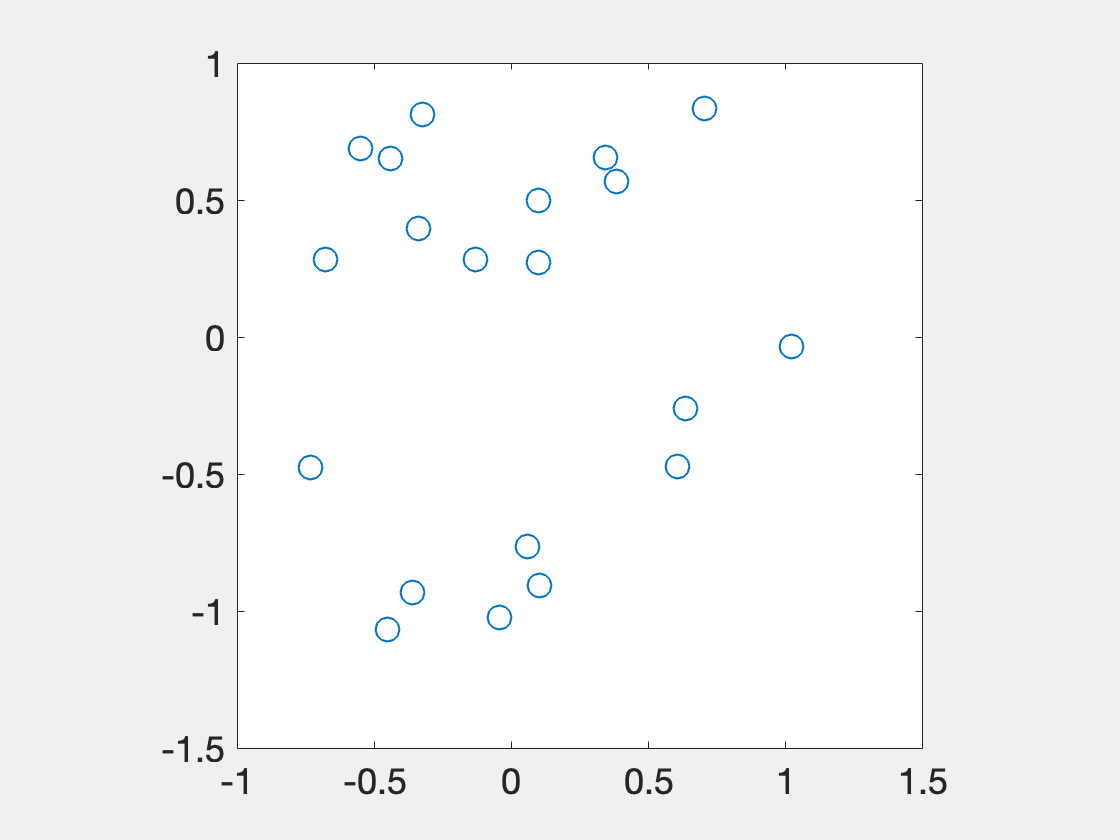

n   = 20; % number of points
d   = 2;  % dimension
o   = ones(n,1);
K   = @(X) diag(X)*o' + o*diag(X)' - 2*X;

% Make some sample data in [-1,1]x[-1,1]
rng(1);
X0  = 2*(rand(n,d)-.5);
% Put center-of-mass at zero
X0 = X0 - repmat( ones(1,n)/n*X0, n, 1 );

% Plot it:
figure(1); clf;
h=plot( X0(:,1), X0(:,2) , 'o','MarkerSize',12);
% h.MarkerFaceColor = h.Color;
set(gca,'fontsize',18)
hold all
axis square

## Observe only some pairwise distances

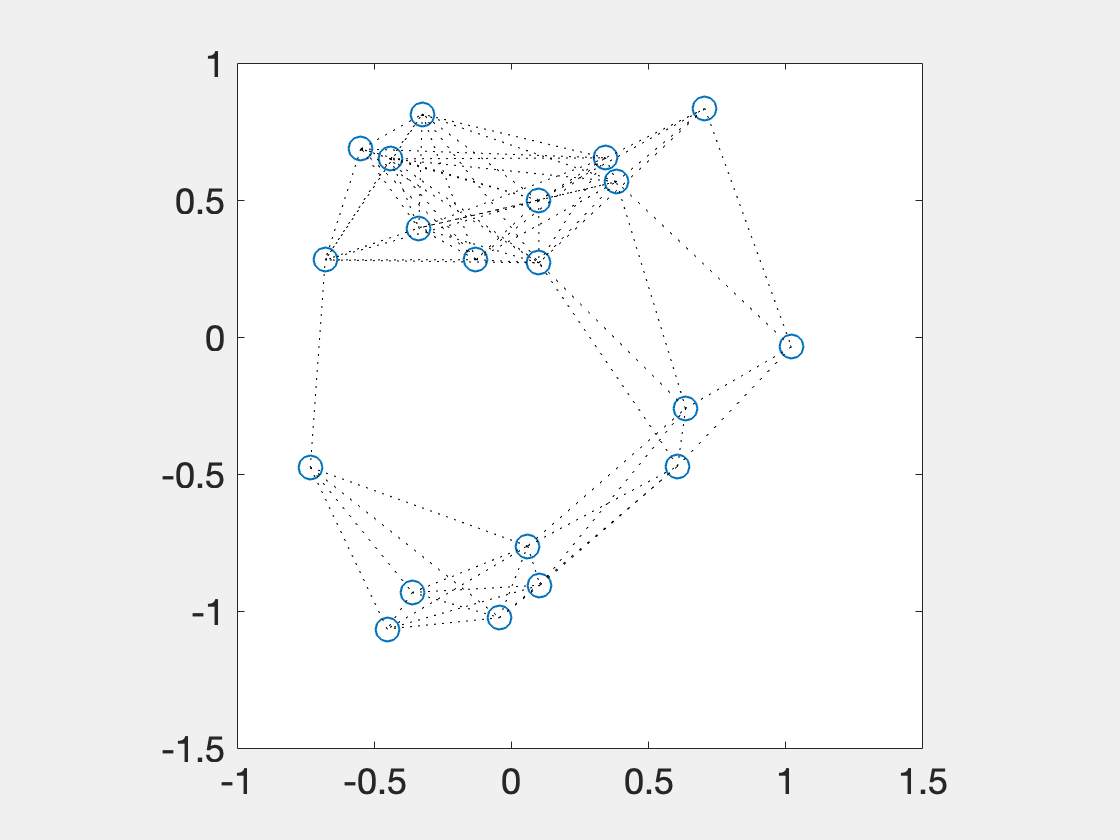

figure(1); clf;
h=plot( X0(:,1), X0(:,2) , 'o','MarkerSize',12);
% h.MarkerFaceColor = h.Color;
set(gca,'fontsize',18)
hold all
axis square

% Only observe some of these
E   = K(X0*X0');

% min_dist    = 0.86; % this should give perfect recovery
min_dist    = 0.85; % this should not
E_thresh    = ( E < min_dist );
E_thresh    = E_thresh - tril(E_thresh);
for i = 1:n
    for j = find( E_thresh(i,:) )
        if ~isempty(j)
            hold all
            plot( [X0(i,1),X0(j,1)], [X0(i,2),X0(j,2) ], 'k:' );
        end
    end
end


omega   = find( E_thresh(:) );
obs     = @(y) y(omega);
fprintf('Using %d pairwise observations\n',length(omega))

Using 74 pairwise observations


## Solve the SDP using CVX

% Solve SDP using CVX
cvx_begin quiet
    variable XX(n,n) symmetric
%    minimize norm( obs(vec(K(XX))) - obs(vec(E)) )
    minimize trace( XX )
    subject to
        XX*o == zeros(n,1)
        XX   == semidefinite(n)
        obs( vec(K(XX))) == obs(vec(E)) % if we know there is no noise
cvx_end

numericalRank   = @(X) length( find(svd(X) > 1e-3) );
fprintf('Approximate rank of solution is %d\n', numericalRank(XX) );

Approximate rank of solution is 2


s = svd(XX);
disp(s(1:5))

    8.6550
    4.6465
    0.0000
    0.0000
    0.0000



## Recreate data from XX

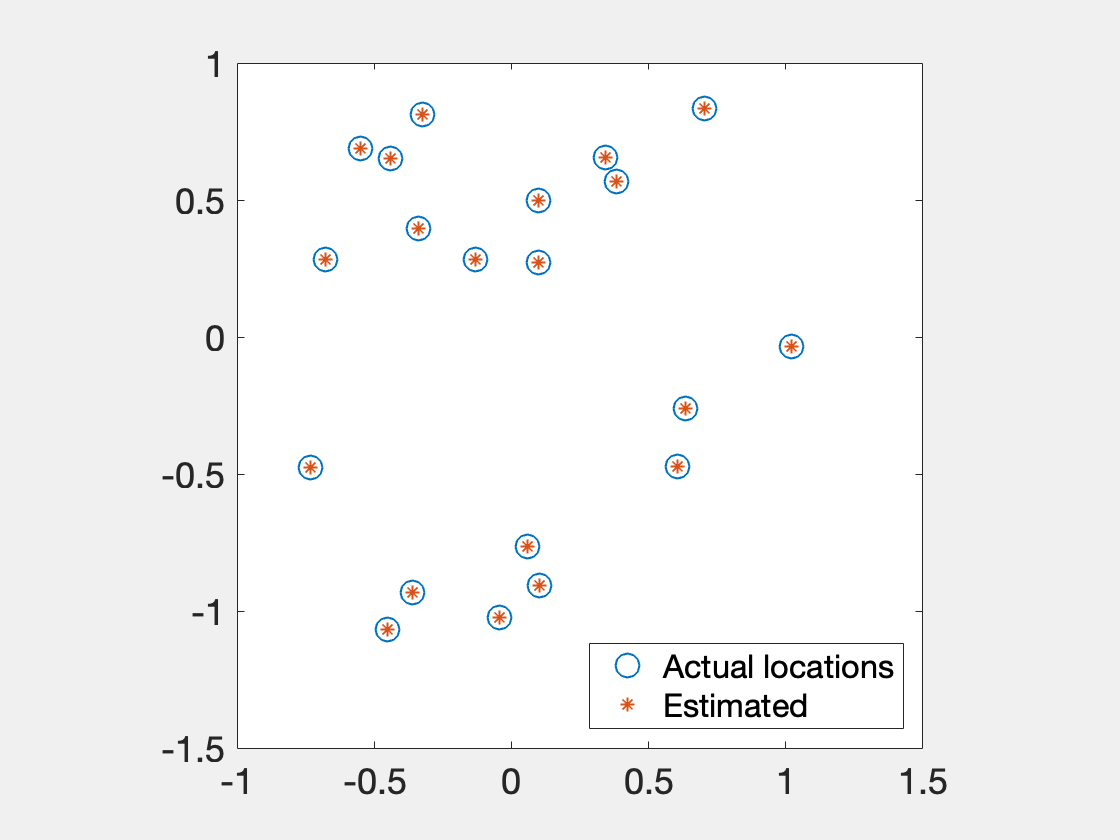

% We want to find the *right* X such that X*X' = XX
[V,D]   = eig( XX );
[eigv,ind] = sort( diag(D), 'descend' );
X       = V(:,ind(1:2))*diag( sqrt(eigv(1:2)) );

% Solve Procrustes problem to find best rotation
[u,~,v] = svd(X0'*X,'econ');
R       = u*v';
X       = X*R'; 

figure(1); clf;
h=plot( X0(:,1), X0(:,2) , 'o','MarkerSize',12);
% h.MarkerFaceColor = h.Color;
set(gca,'fontsize',18)
hold all
axis square
hold all
hh  = plot( X(:,1), X(:,2), '*' );
legend([h,hh],'Actual locations','Estimated','location','southeast');